# Frequency Response Analysis of Lure-Type Reset Control Systems

This script demonstrates how to compute a pseudo-sensitivity for a Lure-type reset control system.

A simple example plant is used, consisting of a mass-system with a transport delay. First, a simple linear PID controller is tuned according to widely-used rules-of-thumb. Subsequently, the integrator is replaced with a reset-based integrator. Then, the pseudo-sensitivity is computed, which shows that the reset-based controller outperforms its linear equivalent.

clearvars; clc;
close all;

% General variable declarations
s = tf('s');        % Laplace variable
lineWidth = 1.5;    % Figure line-width

## **Load example-plant** (mass-system with transport delay)


$$P(s) = \frac{1}{ms^2} \cdot e^{-T_d \cdot s}$$


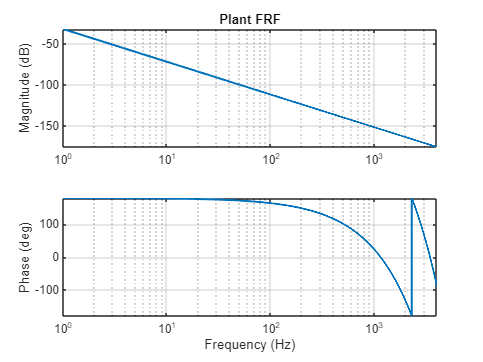

m = 1;              % Plant mass
Td = 4.375e-4;      % Transport delay
freqs = 1:1:4000;   % Frequency vector (Hz)

tfPlant = exp(-Td*s) / (m*s^2);                     % Transfer function
frfPlant = squeeze(freqresp(tfPlant,freqs,'Hz')).'; % Frequency-response function

% Plot plant
figure; tiledlayout("vertical")
nexttile
semilogx(freqs,mag2db(abs(frfPlant)),LineWidth=lineWidth);
grid on; axis tight;
ylabel('Magnitude (dB)'); title('Plant FRF')

nexttile
semilogx(freqs,rad2deg(angle(frfPlant)),LineWidth=lineWidth);
grid on; axis tight;
xlabel('Frequency (Hz)'); ylabel('Phase (deg)')

## **Load linear example-controller** (rule-of-thumb PID)

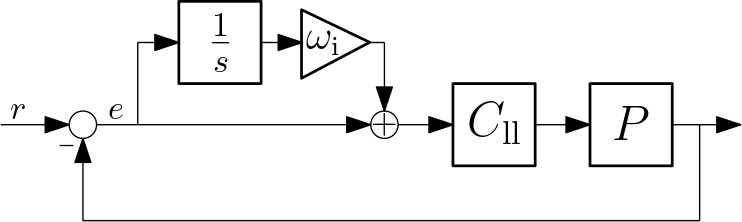


$$C_\mathrm{ll}(s) = K_p \cdot \frac{\left(1+\frac{s}{\omega_\mathrm{d}}\right)}{\left(1+\frac{s}{\omega_\mathrm{l}}\right)}$$



$$\omega_\mathrm{i} = \frac{\omega_\mathrm{BW}}{5}, \quad \omega_\mathrm{d} = \frac{\omega_\mathrm{BW}}{3}, \quad \omega_\mathrm{l} = 3\omega_\mathrm{BW}$$


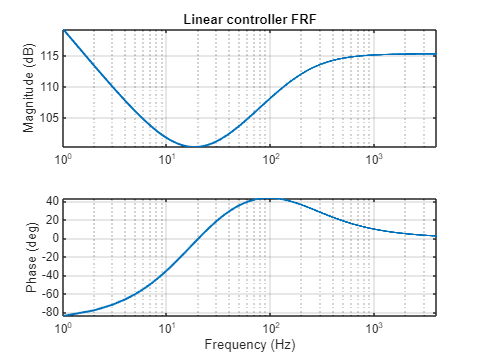

wBW = 2*pi*71;  % Open-loop crossover frequency which gives a 6dB sensitivity-peak (rad/s)
wi = wBW / 5;   % Integrator-frequency (rad/s)
wd = wBW / 3;   % Lead-frequency (rad/s)
wl = wBW * 3;   % Lag-frequency (rad/s)

% Controller without correct gain
tfClin_noGain = (1 + wi/s) * (1+s/wd) / (1+s/wl);

% Find controller gain that yields the desired open-loop crossover frequency
Kp = 1 / abs(squeeze(freqresp(tfPlant*tfClin_noGain,wBW)));
tfClin = Kp * tfClin_noGain;  % Transfer function of linear controller

frfCtrlLin = squeeze(freqresp(tfClin,freqs,'Hz')).';    % Controller FRF
frfOLlin = frfCtrlLin .* frfPlant;                      % Open-loop FRF

% Plot linear controller
figure; tiledlayout("vertical")
nexttile
semilogx(freqs,mag2db(abs(frfCtrlLin)),LineWidth=lineWidth);
grid on; axis tight;
ylabel('Magnitude (dB)'); title('Linear controller FRF')

nexttile
semilogx(freqs,rad2deg(angle(frfCtrlLin)),LineWidth=lineWidth);
grid on; axis tight;
xlabel('Frequency (Hz)'); ylabel('Phase (deg)')

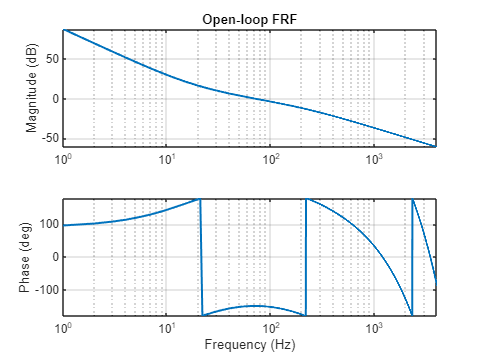


% Plot open-loop
figure; tiledlayout("vertical")
nexttile
semilogx(freqs,mag2db(abs(frfOLlin)),LineWidth=lineWidth);
grid on; axis tight;
ylabel('Magnitude (dB)'); title('Open-loop FRF')

nexttile
semilogx(freqs,rad2deg(angle(frfOLlin)),LineWidth=lineWidth);
grid on; axis tight;
xlabel('Frequency (Hz)'); ylabel('Phase (deg)')

## Construct controller with reset-based integrator

We replace the integrator in the linear controller with the reset-based variant developed in:

- [1] L. F. van Eijk, Y. Liu, X. Zhang, D. Kostić, and S. H.HosseinNia, "A Nonlinear Integrator Based on the First-Order Reset Element", in IFAC-PapersOnLine 58(7), 2024, pp. 382-387.

By using the reset-based variant, the integrator introduces less phase lag. We use this advantage to increase the integrator frequency, resulting in reduced sensitivity in the low-frequency range without increasing the sensitivity-peak

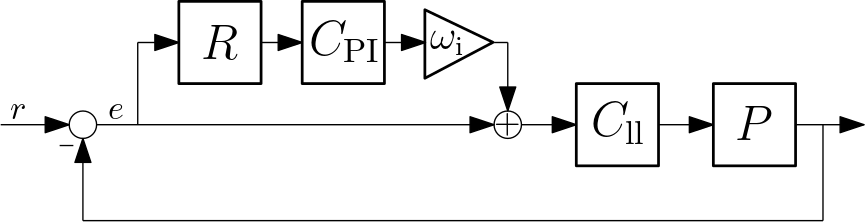

wi_NL = 1.48*wi;    % Increase the integrator-frequency
gamma = 0;          % Choose reset fraction (see [1] for more information)
wc = 1*wi_NL;       % Choose phase-shift frequency equal to integrator frequency (see [1] for more information)

% Construct reset-based integrator
tfC_PI = (wc + s) / (wc*s);                     % (7) in [1]
theta_D_inf = (4*(1-gamma)) / (pi*(1+gamma));   % (8) in [1]  
wr = wc / sqrt(1+theta_D_inf^2);                % (8) in [1]
sysR.A_R = -wr; sysR.B_R = wr; sysR.C_R = 1;    % Reset element as in (1) of [1]

## Convert system into Lure-form

Using the function `convertToLure()`, we can convert the system on the left into the Lure-form shown on the right. Therefore, we will now write our system into the necessary form before conversion.

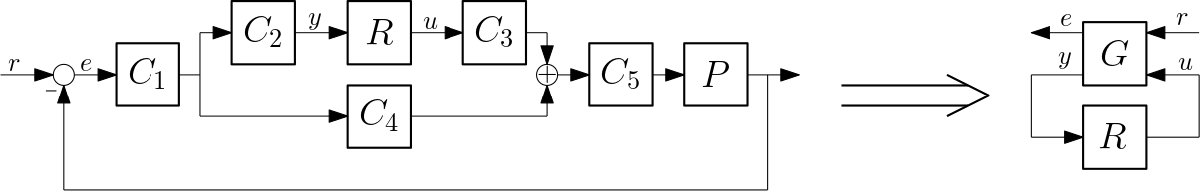

[frfC1, frfC2, frfC4] = deal(ones(size(freqs)));    % Simply unit gains (direct feedthrough)

tfC3 = wi_NL * tfC_PI;
frfC3 = squeeze(freqresp(tfC3,freqs,'Hz')).';

tfC5 = Kp * (1+s/wd) / (1+s/wl);    % Remainder of linear controller
frfC5 = squeeze(freqresp(tfC5,freqs,'Hz')).';

[frfGwz, frfGuz, frfGwy, frfGuy] = convertToLure(frfC1, frfC2, frfC3, frfC4, frfC5, frfPlant);   % Convert into Lure-type form

## Compute the pseudo-sensitivity

Compute the pseudo-sensitivity and underlying higher-order sinusoidal-input sensitivity functions (HOSISFs) using the function `computePseudoSens()`.

tic
[pseudoSensMag, HOSISFs_re] = computePseudoSens(freqs, sysR, gamma, frfGwz, frfGuz, frfGwy, frfGuy);
toc

Elapsed time is 41.596565 seconds.


## Compare (pseudo-)sensitivity of linear and reset controller

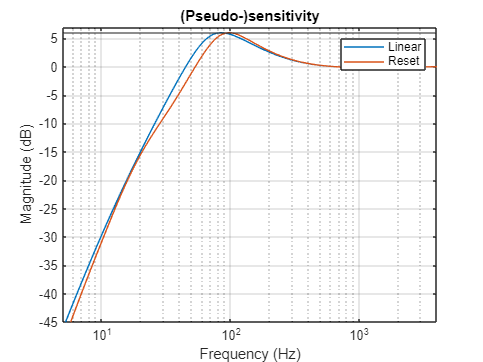

frfSensLin = 1 ./ (1 + frfPlant .* frfCtrlLin); % Sensitivity with linear controller

% Plot (pseudo-)sensitivity
figure
semilogx(freqs,mag2db(abs(frfSensLin)))
hold on; grid on;
semilogx(freqs,mag2db(abs(pseudoSensMag)))
axis([5, freqs(end), -45, 7])
yline(6)
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)')
title("(Pseudo-)sensitivity")
legend('Linear','Reset')

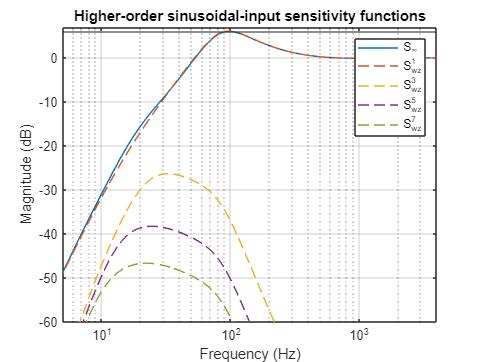


% Plot HOSISFs
figure
semilogx(freqs,mag2db(abs(pseudoSensMag)))
hold on; grid on;
for nn = 1:2:7
    semilogx(freqs,mag2db(abs(HOSISFs_re(nn,:))),'--')
end
axis([5, freqs(end), -60, 7])
yline(6)
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)')
title("Higher-order sinusoidal-input sensitivity functions")
legend('S_\infty','S_{wz}^1','S_{wz}^3','S_{wz}^5','S_{wz}^7')